# 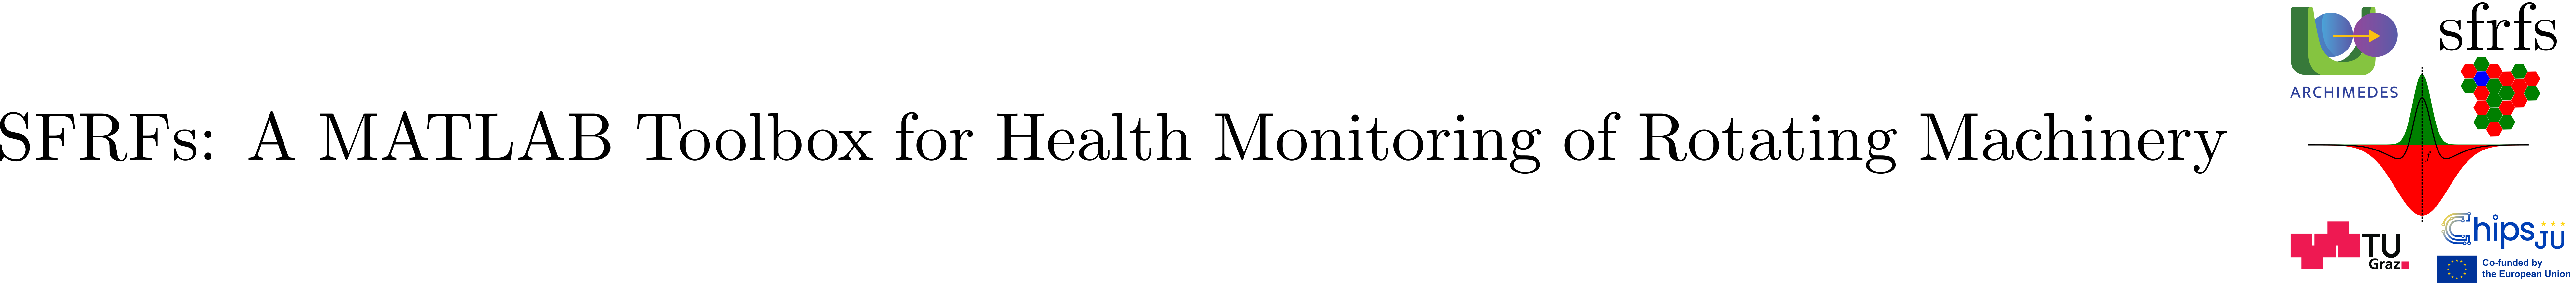

# ParametersRollingBearings

## Summary

Class encapsulating the geometric and configuration parameters of a rolling element bearing.

Key properties (set at construction):

- `numRollingElements`: Integer number of rolling elements (balls or rollers) in the bearing.

- `ballDiameter`: Diameter of each rolling element in millimeters.

- `pitchDiameter`: Pitch diameter of the bearing in millimeters.

- `contactAngle`: Contact angle between rolling elements and races in degrees (0 to 90).

Features:

- Constructor accepts name-value pairs with validation for each parameter.

- All properties are immutable after construction ensuring consistent bearing geometry representation.

- Provides a formatted string output summarizing the bearing parameters for logging and diagnostics.

Creating a bearing parameters object is required for fault frequency band computations and condition monitoring of rolling bearings.

## Description

Knowledge of the bearing's physical parameters is essential for accurate health monitoring and fault diagnosis. Depending on the faulty element and the geometry of the bearing the vibration spectra will manifest characteristic patterns. This value object captures the well known geometry parameters that allow to define the monitoring fault frequency bands.

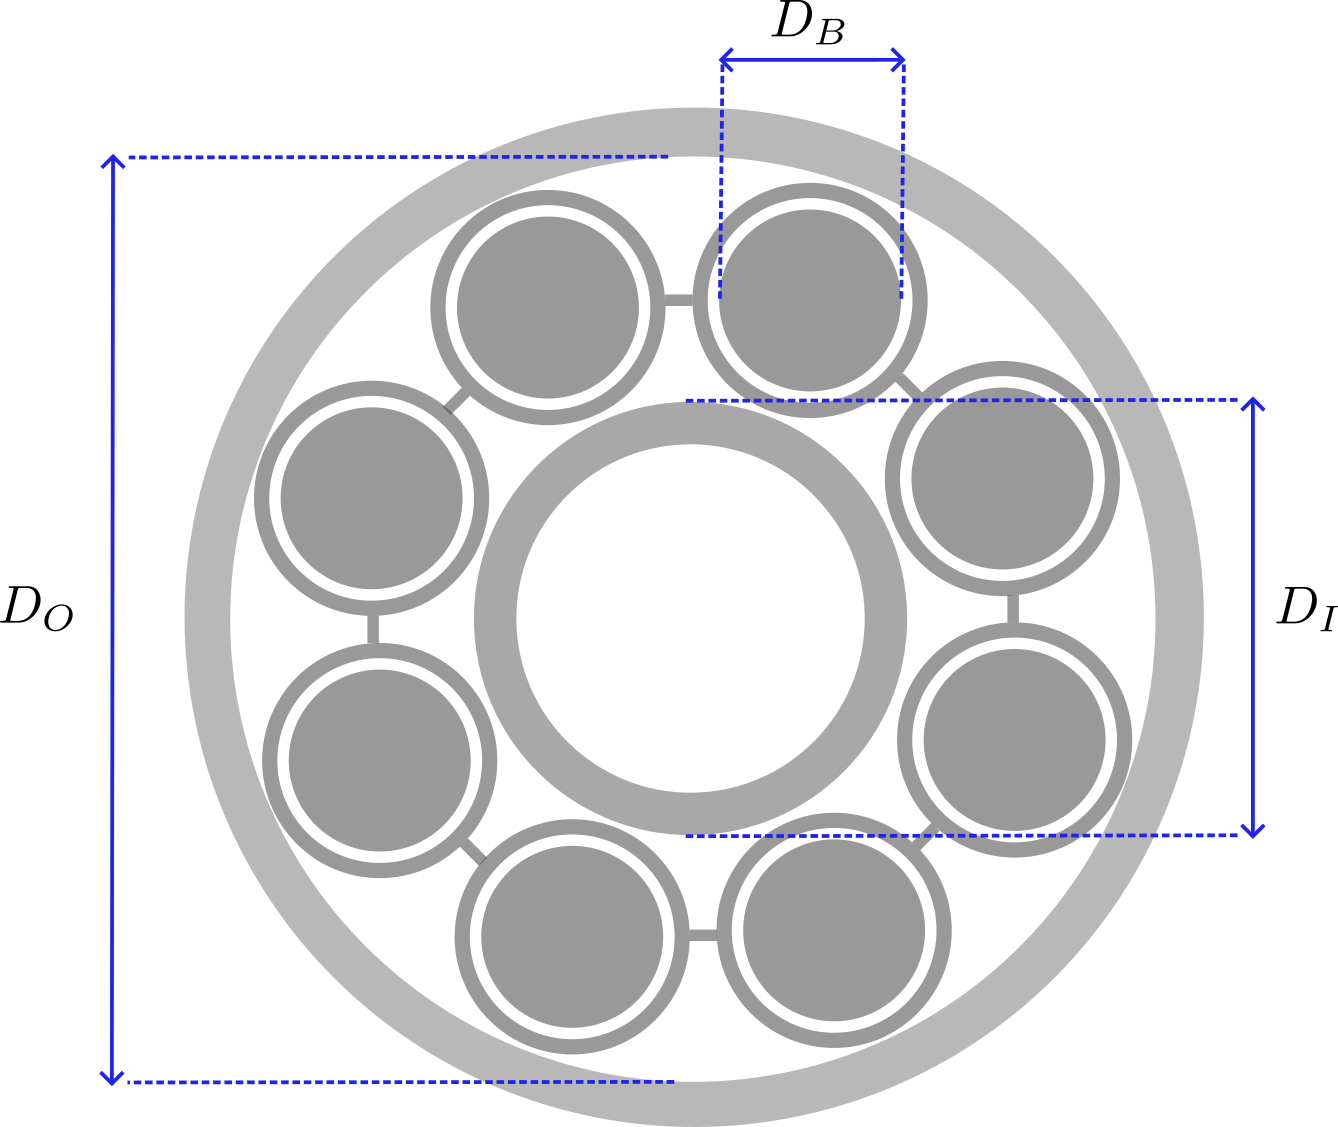

**Figure 1**. Schematic diagram of bearing geometry and parameters. Symbols: $$D_B$$ = rolling element (ball) diameter;$$D_O$$ = outer raceway diameter; $$D_I$$ = inner raceway diameter.

## Example

We define bearing geometry parameters applicable to the [**XJTU-SY**](https://github.com/WangBiaoXJTU/xjtu-sy-bearing-datasets) rolling bearing run-to-failure dataset (see Reference [1]).

**Table 1**. Relevant design parameters of the heavy duty bearing [LDK UER204](https://www.ldk-bearings.com/products/uer2-insert-bearing-chrome-steel-bearing/).

### Object creation

Creating the bearing parameters for bearing in Table 1 is achieved as follows:

% create the parameters for the bearing
bp = ParametersRollingBearings( ...
            'numRollingElements',8, ...
            'ballDiameter',7.92, ...
            'pitchDiameter',34.55, ...
            'contactAngle',0)

bp =   ParametersRollingBearings with properties:

    numRollingElements: 8
          ballDiameter: 7.9200
         pitchDiameter: 34.5500
          contactAngle: 0


### `String representation`

The class is a value object and provides a (json) string rendering via toString method.

% string representation for the operating conditions table
disp(bp.toString());

[ParametersRollingBearings: numRollingElements: 8, ballDiameter: 7.920 mm, pitchDiameter: 34.550 mm, contactAngle: 0.00 degrees]


## API documentation

### MATLAB help

help ParametersRollingBearings

 PARAMETERSROLLINGBEARINGS Bearing geometry and configuration parameters
 
    Geometric parameters of a rolling element bearing:
    number and size of rolling elements, pitch diameter, and contact angle.
 
    All properties are public and set during construction.
 
    Properties (all mandatory):
        NumRollingElements (integer >= 1)
            Number of rolling elements (balls/rollers) in the bearing.
 
        BallDiameter (double > 0) [mm]
            Diameter of each rolling element.
 
        PitchDiameter (double > 0) [mm]
            Pitch diameter of the bearing.
 
        ContactAngle (double, 0 <= angle <= 90) [degrees]
            Contact angle between the rolling elements and the races.
 
    Example:
        bp = ParametersRollingBearings( ...
            'numRollingElements',8, ...
            'ballDiameter',7.92, ...
            'pitchDiameter',34.55, ...
            'contactAngle',0);
 
    See also: bearingFaultBands, BearingFrequencyBands

    Documentation fo

### MATLAB documentation

doc ParametersRollingBearings

Opens the full class documentation in the MATLAB Help Browser, including formatted examples, links to related functions, and extended descriptions.

## Source code

The value object class for bearing geometry parameters is [ParameterRollingBearings](matlab:open('../../ParametersRollingBearings.m')).

## Test

Unit testing for the class is implemented in [TestParametersRollingBearings](matlab:open('../../../tests/TestParametersRollingBearings.m')).

% execute tests
res = runtests('Spectral Fault Receptive Fields/tests/TestParametersRollingBearings');

Running TestParametersRollingBearings
.......... .
Done TestParametersRollingBearings
__________



% display summary of tests
SFRFsTestUtil.printTestSummary(res,80);

Test Name                                                                        | Result
-----------------------------------------------------------------------------------------
TestParametersRollingBearings/testValidConstruction                              | Passed
TestParametersRollingBearings/testMissingArgumentsError                          | Passed
TestParametersRollingBearings/testInvalidTypeError                               | Passed
TestParametersRollingBearings/testInvalidValueError                              | Passed
TestParametersRollingBearings/testImmutablePropertyError                         | Passed
TestParametersRollingBearings/testNegativeRollingElements                        | Passed
TestParametersRollingBearings/testZeroBallDiameter                               | Passed
TestParametersRollingBearings/testNegativePitchDiameter                          | Passed
TestParametersRollingBearings/testNegativeContactAngle                           | Passed
TestParame

## How to cite this work

Muñoz Gutiérrez, Stan, & Wotawa, Franz (2025). SFRFs: A MATLAB Toolbox for Health Monitoring of Rotating Machinery. Zenodo. DOI: [10.5281/zenodo.17631784](http://10.0.20.161/zenodo.17631784).

## References

- [1] Biao Wang, Yaguo Lei, Naipeng Li, Ningbo Li, “A Hybrid Prognostics Approach for Estimating Remaining Useful Life of Rolling Element Bearings”, IEEE Transactions on Reliability, pp. 1-12, 2018. [DOI: 10.1109/TR.2018.2882682](https://doi.org/10.1109/TR.2018.2882682).